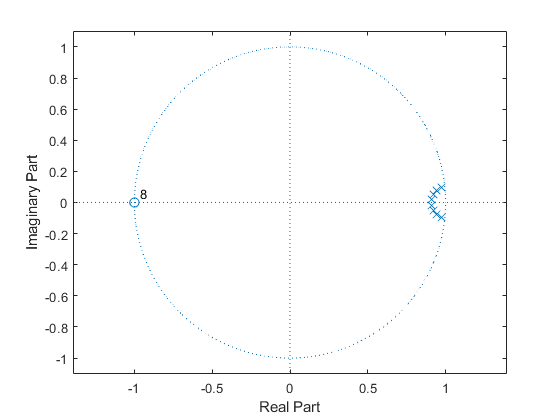

% Problem 1:
fs = 720;
Wp = 10/(fs/2);
Ws = 20/(fs/2);

% Order and cutoff freq 
[n,Wn] = buttord(Wp,Ws,2,40);
% n,Wn*(fs/2)

% Transfer function 
[b,a] = butter(n,Wn,"low");
% b,a

% Pole-Zero plot
[z,p,k] = butter(n,Wn,"low");
zplane(z,p)

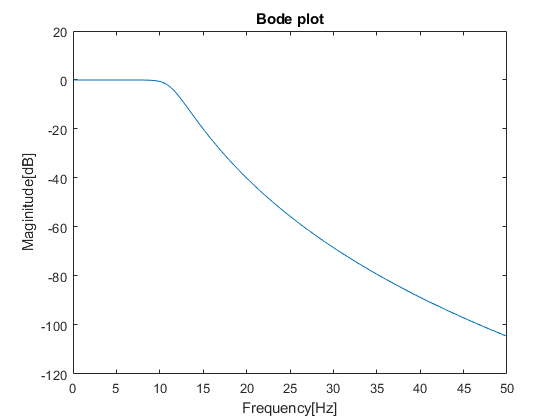


% Bode plot 
% Bode plot 
H = tf(b,a,1/fs);
f = linspace(0,50,100);
[mag,phase] = bode(H,2*pi*f);
plot(f,db(squeeze(mag)))
xlabel("Frequency[Hz]")
ylabel("Maginitude[dB]")
title("Bode plot")

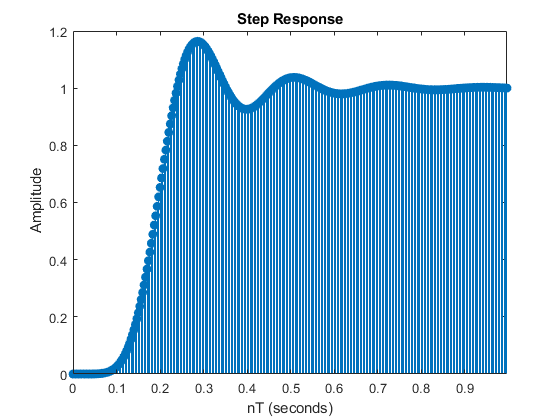


% Impulse response
impz(b,a,300,300)

% Step response
stepz(b,a,300,300)

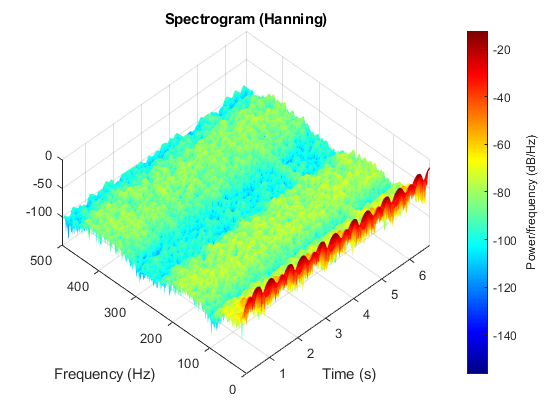

% Problem 2:
s = load("ECG_Data.txt");
t1 = 0:1/length(s):1-1/length(s);
fs1 = 1000;

% Spectrogram
spectrogram(s,hann(300),290,800,fs1,'yaxis');view(-45,65);colormap jet
title('Spectrogram (Hanning)');

% Pitch Extraction
[~,f,t,ps] = spectrogram(s,hann(2000),1999,4000,fs1,'xaxis');colormap jet

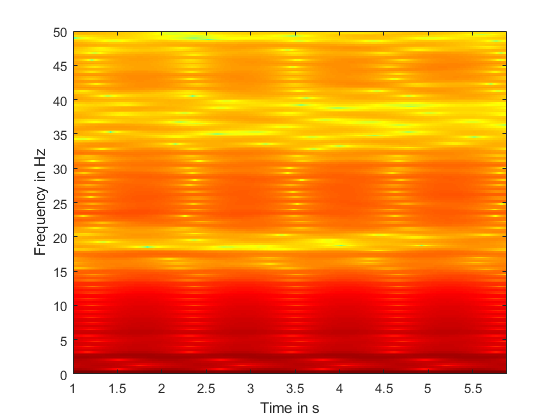

imagesc(t, f, 10*log10(ps));
axis xy;
ylim([0 50]); % zoom to the fundamental frequency range
xlabel('Time in s');
ylabel('Frequency in Hz');

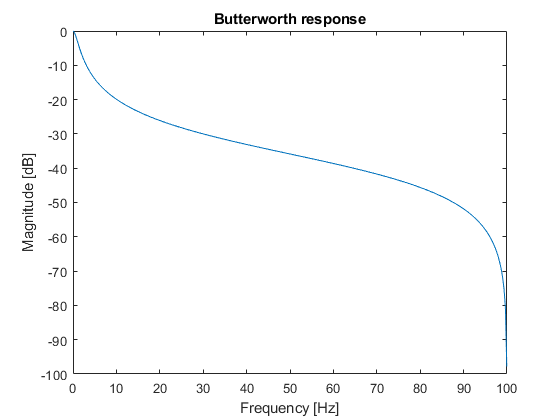


% Butterworth filter(0-30 Hz;10,-30 dB)
fs_4 = 200;
Wp = 0.5/(fs_4/2);
Ws = 30/(fs_4/2);

% Order and cutoff freq 
[n,Wn] = buttord(Wp,Ws,10,-30);
% n,Wn*(fs/2)

% Transfer function 
[b4,a4] = butter(abs(n),Wn,"low");
w = 0:0.01:pi;
[h,ph] = freqz(b4,a4,w);
m = 20*log10(abs(h));
plot((ph/pi)*100,m)
title('Butterworth response')
ylabel('Magnitude [dB]');
xlabel('Frequency [Hz]');

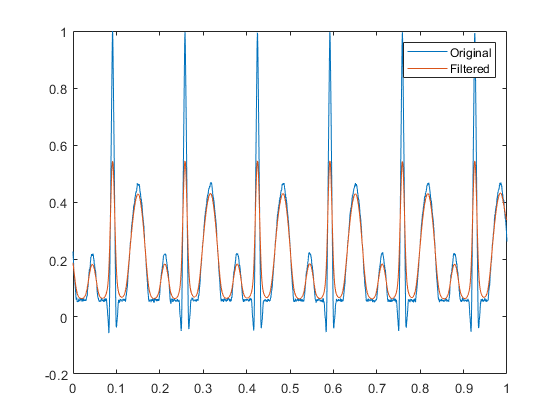


% Filtering 
s_filter = filtfilt(b4,a4,s);
plot(t1,s)
hold on
plot(t1,s_filter)
hold off
legend("Original","Filtered")

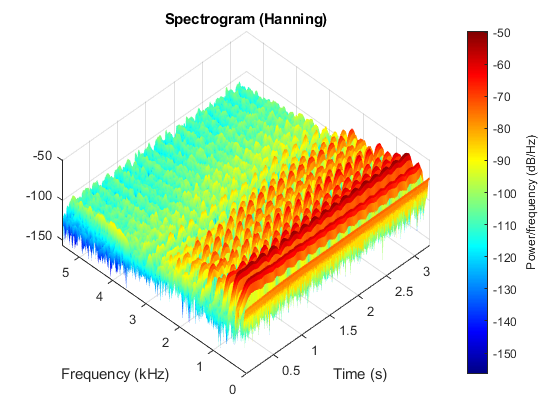

% Problem 3:
% Spectrogram
[s1,f2] = audioread("instru1.wav");
spectrogram(s1,hann(256),250,512,f2,'yaxis');view(-45,65);colormap jet
title('Spectrogram (Hanning)');

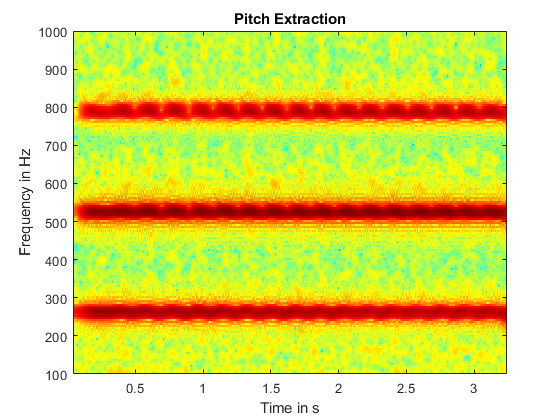


% Pitch Extraction
[~,f,t,ps] = spectrogram(s1,hann(1000),900,2000,f2,'xaxis');
imagesc(t, f, 10*log10(ps));
axis xy;
ylim([100 1000]); % zoom to the fundamental frequency range
xlabel('Time in s');
ylabel('Frequency in Hz');
title('Pitch Extraction');

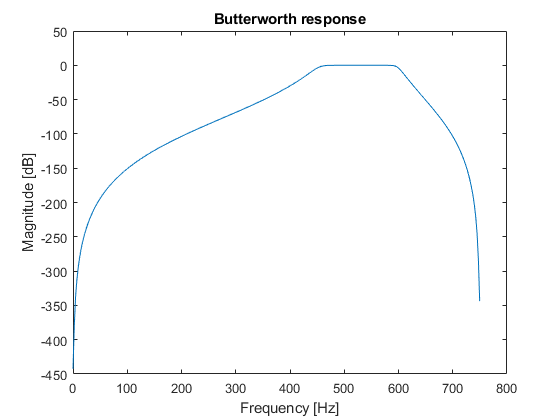


% Butterworth bandpass(450-600 Hz;-60,30 dB)
fs = 1500;
Wp = [450/(fs/2),600/(fs/2)];
Ws = [400/(fs/2),650/(fs/2)];

% Order and cutoff freq 
[n,Wn] = buttord(Wp,Ws,-60,30);
% n,Wn*(fs/2)

% Transfer function 
[b2,a2] = butter(abs(n),Wn,"bandpass");
w = 0:0.01:pi;
[h,freq] = freqz(b2,a2,w);
m = 20*log10(abs(h));
plot((freq/pi)*750,m)
title('Butterworth response')
ylabel('Magnitude [dB]');
xlabel('Frequency [Hz]');

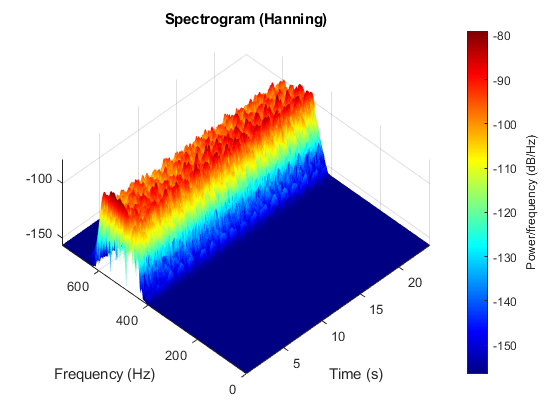


% Filtering 
s1_filter = filtfilt(b2,a2,s1);
t = 0:1/length(s1):1-1/length(s1);

% Spectrogram(filtered)
spectrogram(s1_filter,hann(256),250,512,fs,'yaxis');view(-45,65);colormap jet
title('Spectrogram (Hanning)');

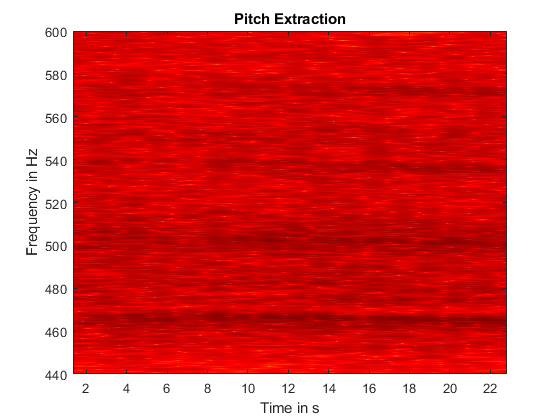


% Pitch Extraction(filtered) 
[~,f,t,ps] = spectrogram(s1_filter,hann(4000),3999,8000,fs,'xaxis');
imagesc(t, f, 10*log10(ps));
axis xy;
ylim([440 600]); % zoom to the fundamental frequency range
xlabel('Time in s');
ylabel('Frequency in Hz');
title('Pitch Extraction');

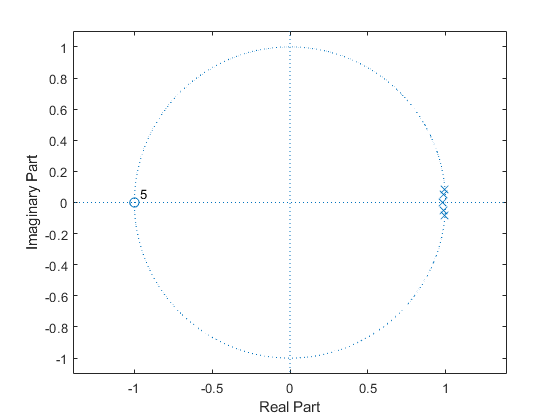

% Problem 4:
fs3 = 720;
Wp3 = 10/(fs3/2);
Ws3 = 20/(fs3/2);

% Order and cutoff freq 
[n4,Wn4] = cheb1ord(Wp3,Ws3,-2,40);
% n,Wn*(fs/2)

% Transfer function 
[b3,a3] = cheby1(n4,2,Wn4,"low");
% b,a

% Pole-Zero plot
[z,p,k] = cheby1(n4,2,Wn4,"low");
zplane(z,p)

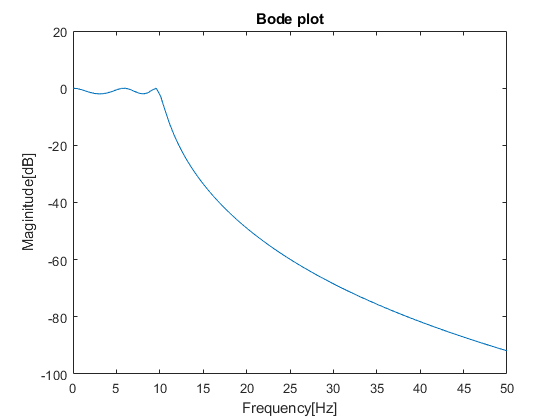


% Bode plot
% Bode plot 
H3 = tf(b3,a3,1/fs3);
f3 = linspace(0,50,100);
[mag3,phase3] = bode(H3,2*pi*f3);
plot(f3,db(squeeze(mag3)))
xlabel("Frequency[Hz]")
ylabel("Maginitude[dB]")
title("Bode plot")

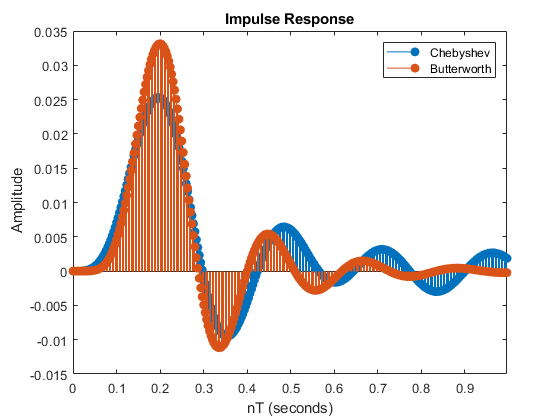



% Impulse response
impz(b3,a3,300,300)
hold on 
impz(b,a,300,300)
hold off
legend('Chebyshev','Butterworth')

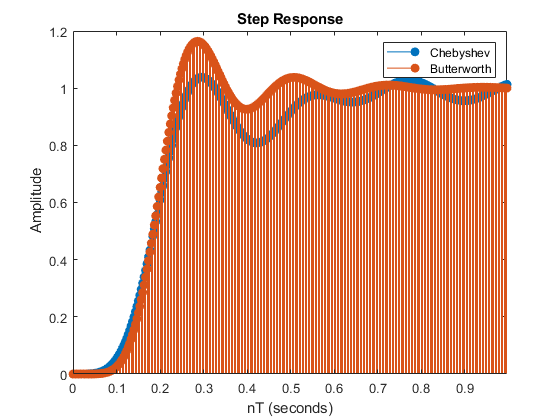


% Step response
stepz(b3,a3,300,300)
hold on 
stepz(b,a,300,300)
hold off
legend('Chebyshev','Butterworth')